# Analysis of Wind Turbine data -- Accleration

#### Dataset: D1C2SG1 -- Accleration labeled data 

**Description:** This dataset is from acclerometers in the tower area of the offshore Wind turbine.

#### Author: Vishu Sharma

#### Last Modified: 29.02.2023

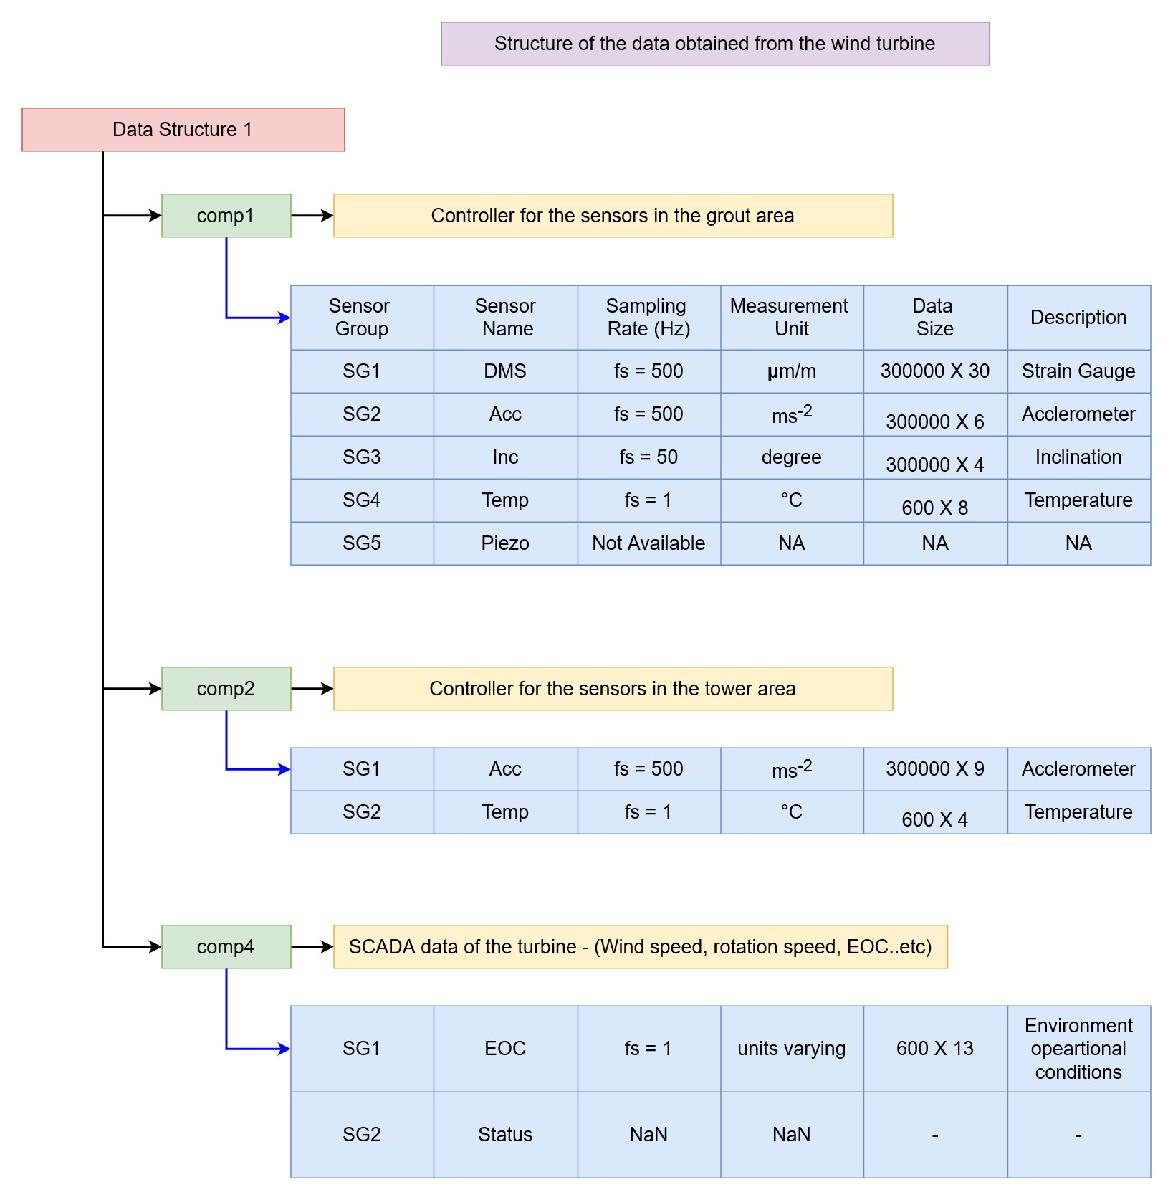

clear all, clc

% Loading data sets from CSV files

A = readmatrix("D:\Vishu_Studienarbeit\WT_labeled_datasets\D1C2SG1_Acc_Labeled.csv");

% Labeled variables for accleration signal 1 (1/3rd CSV only)

Acc1_z     = A(:,1);
Acc1_y     = A(:,2);
Acc1_x     = A(:,3);

% Constructing time vector 

Fs = 500;            % Sampling frequency
T = 1/Fs;            % Sampling period
L = 300000;          % length of signal
t = (0: L-1)*T;      % Time vector

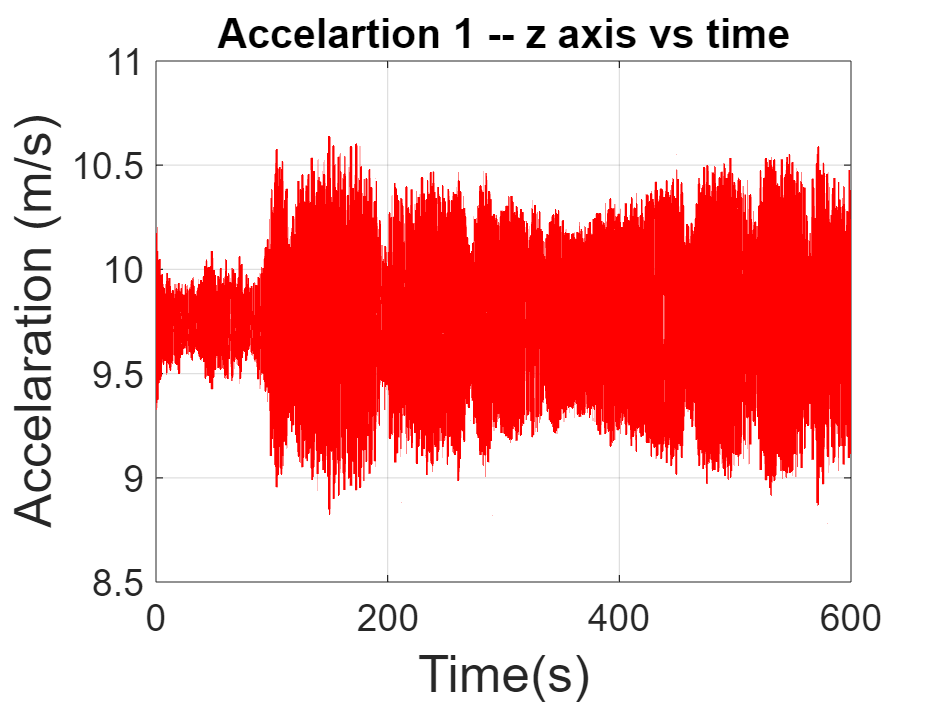

% Time Domain preliminary analysis -- Accelarations 1 z -axis

plot(t, Acc1_z, 'r','LineWidth',1)
title('Accelartion 1 -- z axis vs time','FontSize', 22)

ax = gca;
ax.FontSize = 16;
xlabel('Time(s)','FontSize', 22)
ylabel('Accelaration (m/s)', 'FontSize', 22)

grid on

mean(Acc1_z)

ans = 9.7498

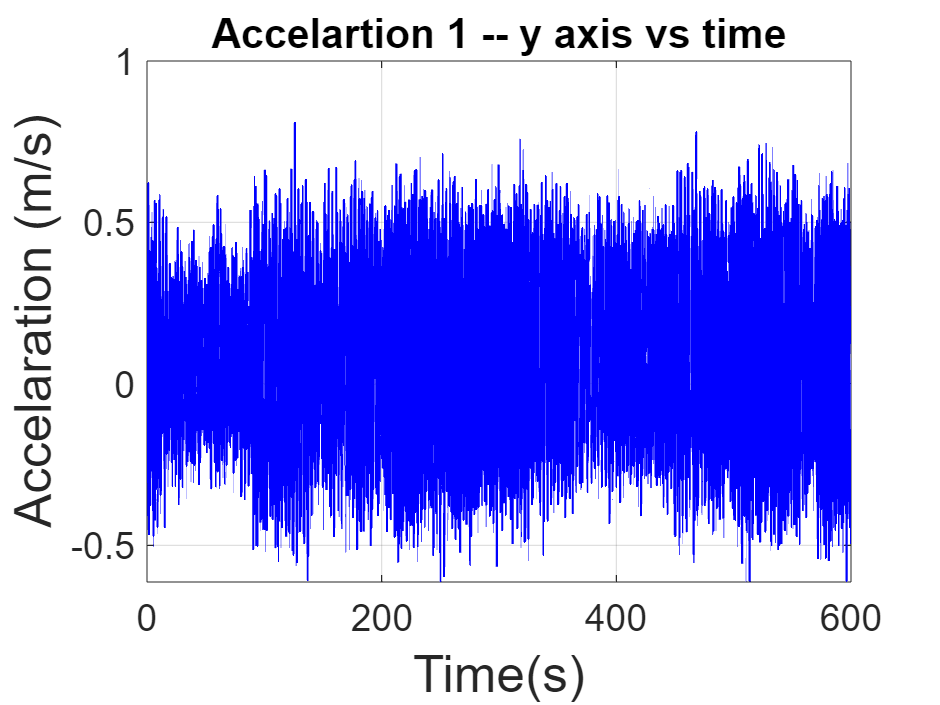

% Time Domain preliminary analysis -- Accelarations 1 y -axis

plot(t, Acc1_y, 'b','LineWidth',1)
title('Accelartion 1 -- y axis vs time','FontSize', 22)

ax = gca;
ax.FontSize = 16;
xlabel('Time(s)','FontSize', 22)
ylabel('Accelaration (m/s)', 'FontSize', 22)

grid on

mean(Acc1_y)

ans = 0.0805

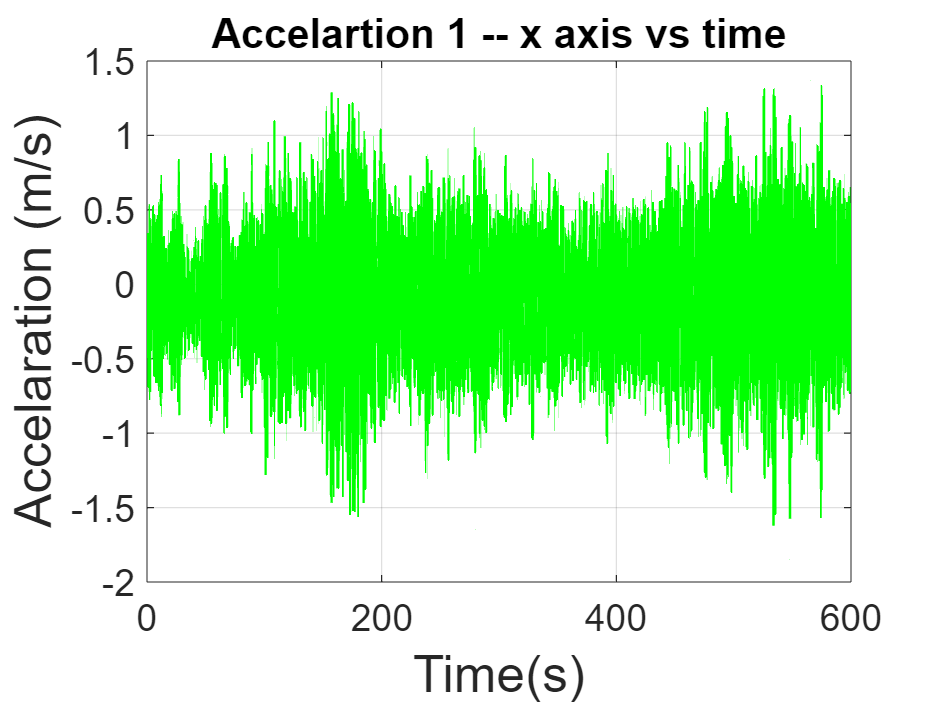

% Time Domain preliminary analysis -- Accelarations 1 x -axis

plot(t, Acc1_x, 'g','LineWidth',1)
title('Accelartion 1 -- x axis vs time','FontSize', 22)

ax = gca;
ax.FontSize = 16;
xlabel('Time(s)','FontSize', 22)
ylabel('Accelaration (m/s)', 'FontSize', 22)

grid on

mean(Acc1_x)

ans = -0.0840

% Zero mean values for accleration

ZM_Acc1_z = Acc1_z - mean(Acc1_z);
ZM_Acc1_y = Acc1_y - mean(Acc1_y);
ZM_Acc1_x = Acc1_x - mean(Acc1_x);

#### Fourier Spectral Analysis of accleration 1 signals

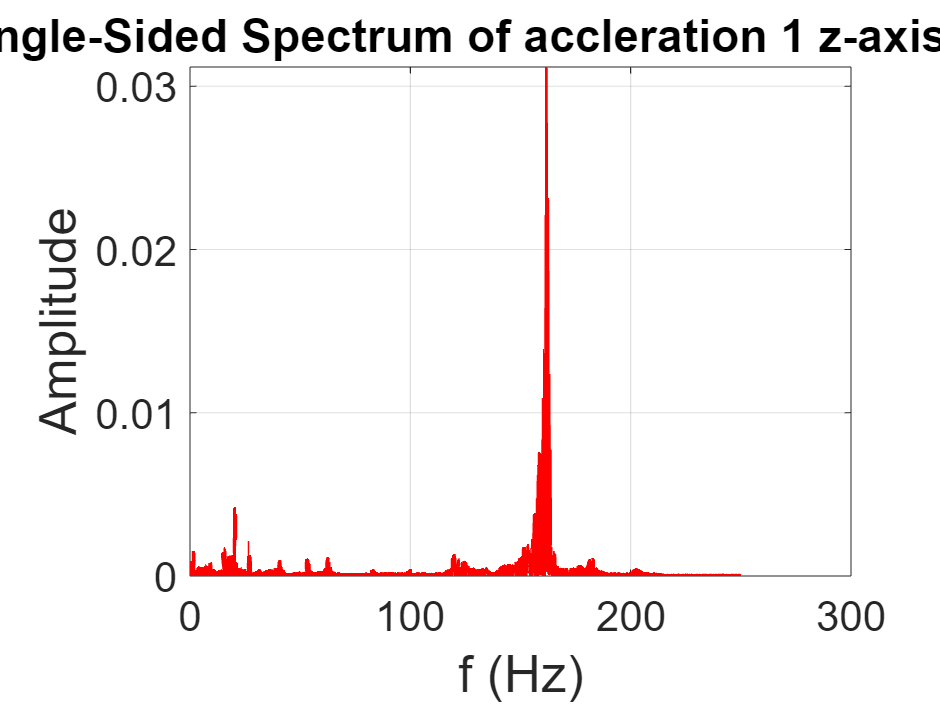

% Fourier Spectrum for z axis accleration - 1


n = 2^nextpow2(L);         % num of points for FFT

Y = fft(ZM_Acc1_z);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1,'r','LineWidth',2) 

title('Single-Sided Spectrum of accleration 1 z-axis signal','FontSize', 22)

ax = gca;
ax.FontSize = 18;
xlabel('f (Hz)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

grid on

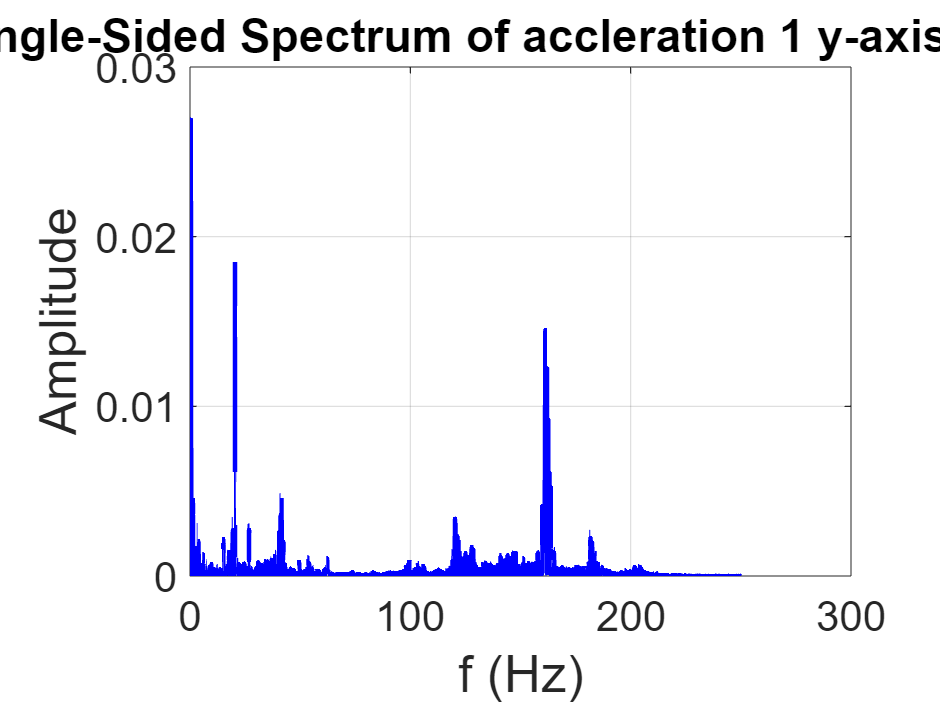

% Fourier Spectrum for y axis accleration - 1


n = 2^nextpow2(L);         % num of points for FFT

Y = fft(ZM_Acc1_y);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1,'b','LineWidth',2) 

title('Single-Sided Spectrum of accleration 1 y-axis signal','FontSize', 22)

ax = gca;
ax.FontSize = 18;
xlabel('f (Hz)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

grid on

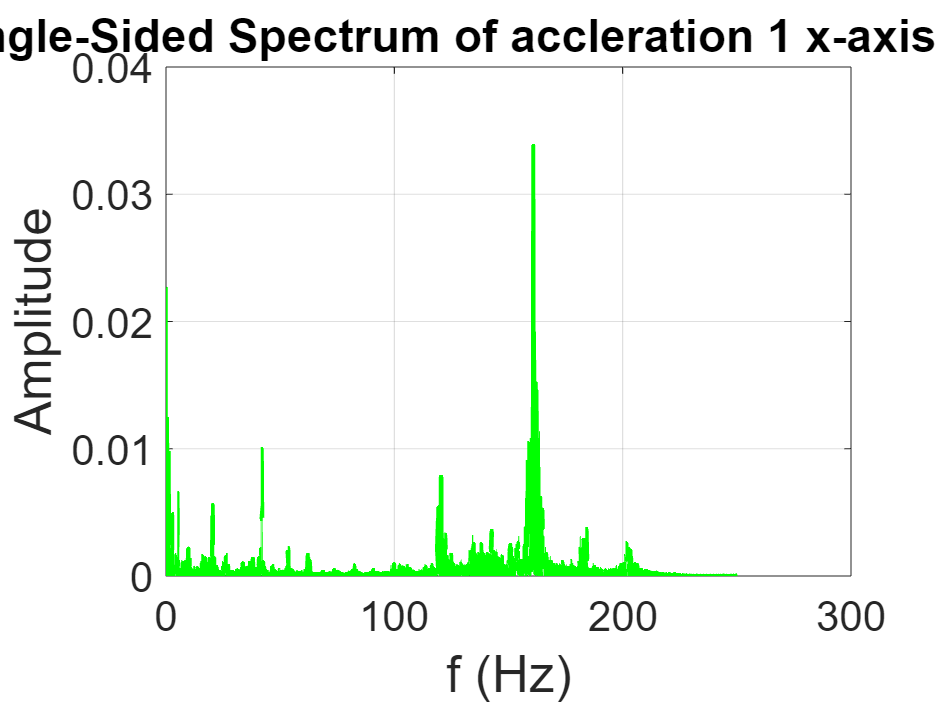

% Fourier Spectrum for x axis accleration - 1


n = 2^nextpow2(L);         % num of points for FFT

Y = fft(ZM_Acc1_x);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1,'g','LineWidth',2) 

title('Single-Sided Spectrum of accleration 1 x-axis signal','FontSize', 22)

ax = gca;
ax.FontSize = 18;
xlabel('f (Hz)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

grid on

#### Spectrograms for accleration 1 signals

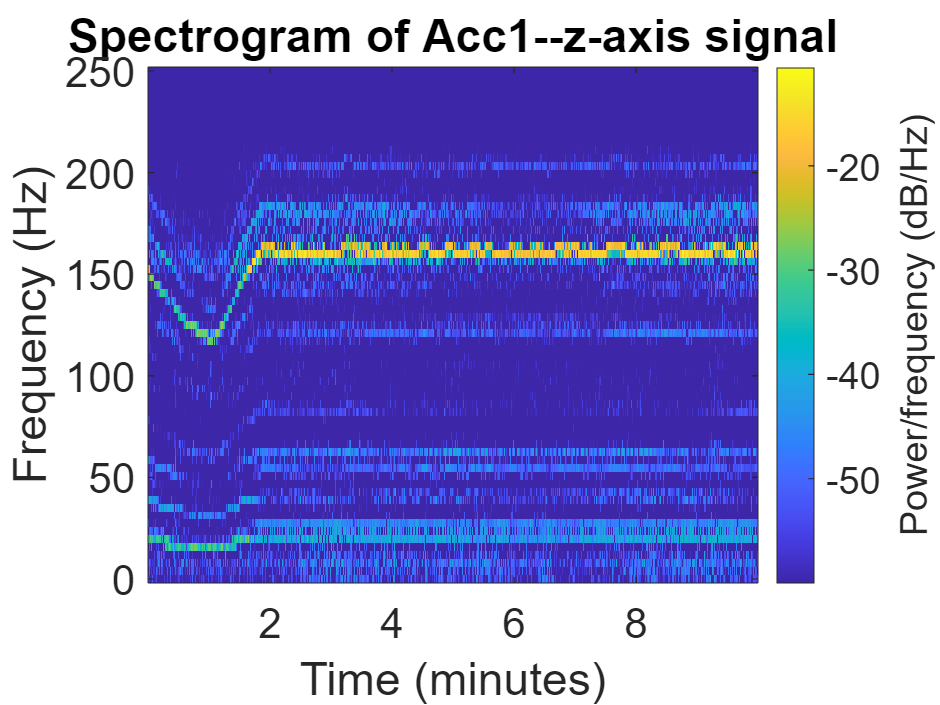

% Spectrogram for z-axis signal

s = spectrogram(ZM_Acc1_z);
spectrogram(ZM_Acc1_z, window(@hanning,128), 64, 128, Fs,'yaxis', 'reassign','MinThreshold', -60)

title('Spectrogram of Acc1--z-axis signal','FontSize', 18)

ax = gca;
ax.FontSize = 18;

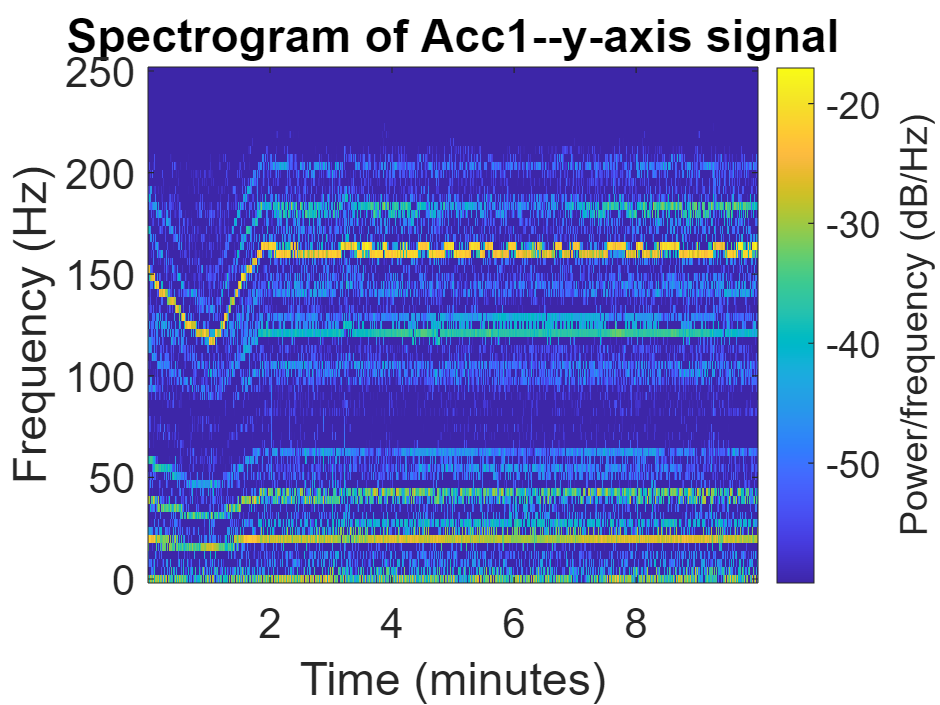

% Spectrogram for y-axis signal

s = spectrogram(ZM_Acc1_y);
spectrogram(ZM_Acc1_y, window(@hanning,128), 64, 128, Fs,'yaxis', 'reassign','MinThreshold', -60)

title('Spectrogram of Acc1--y-axis signal','FontSize', 18)

ax = gca;
ax.FontSize = 18;

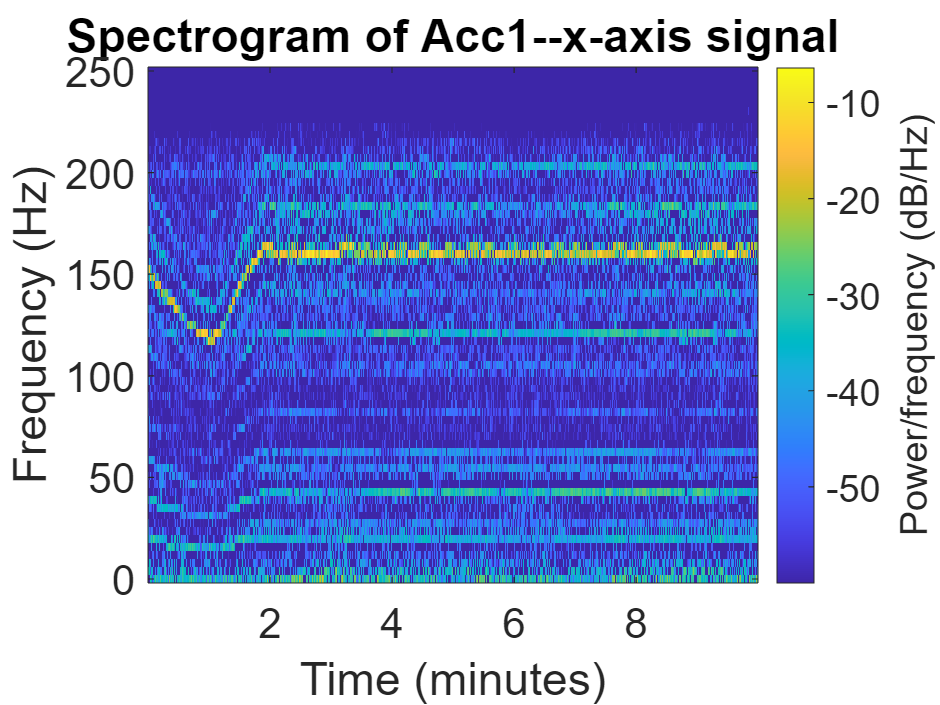

% Spectrogram for x-axis signal

s = spectrogram(ZM_Acc1_x);
spectrogram(ZM_Acc1_x, window(@hanning,128), 64, 128, Fs,'yaxis', 'reassign','MinThreshold', -60)

title('Spectrogram of Acc1--x-axis signal','FontSize', 18)

ax = gca;
ax.FontSize = 18;

#### Hilbert Spectral Analysis for Accleration 1 signal

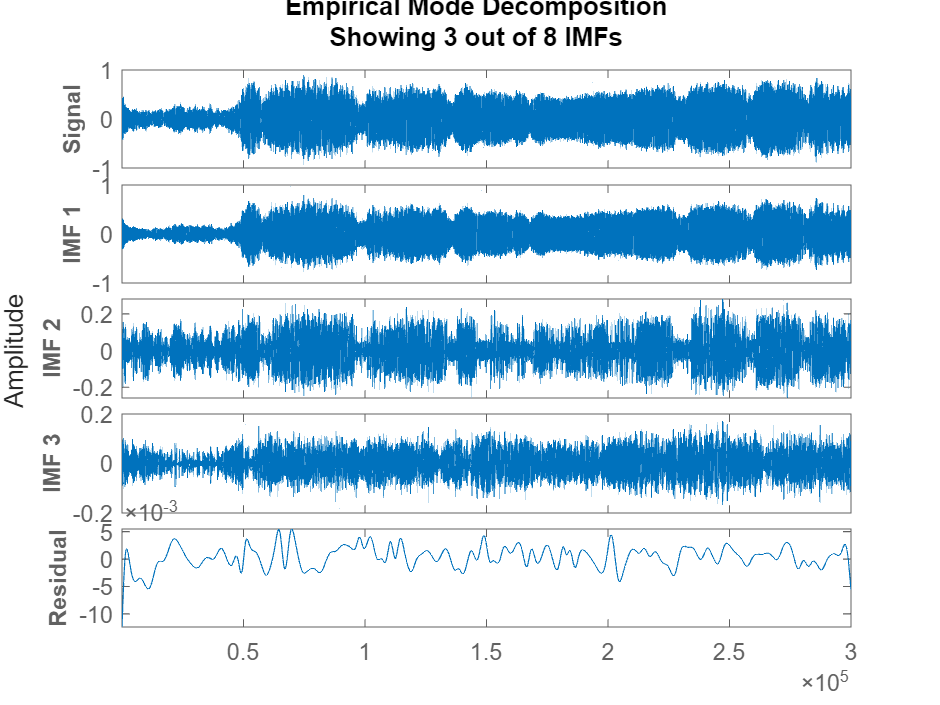

%Hilbert Spectral analysis accleration 1 signal - z axis

emd(ZM_Acc1_z,'MaxNumIMF',9)

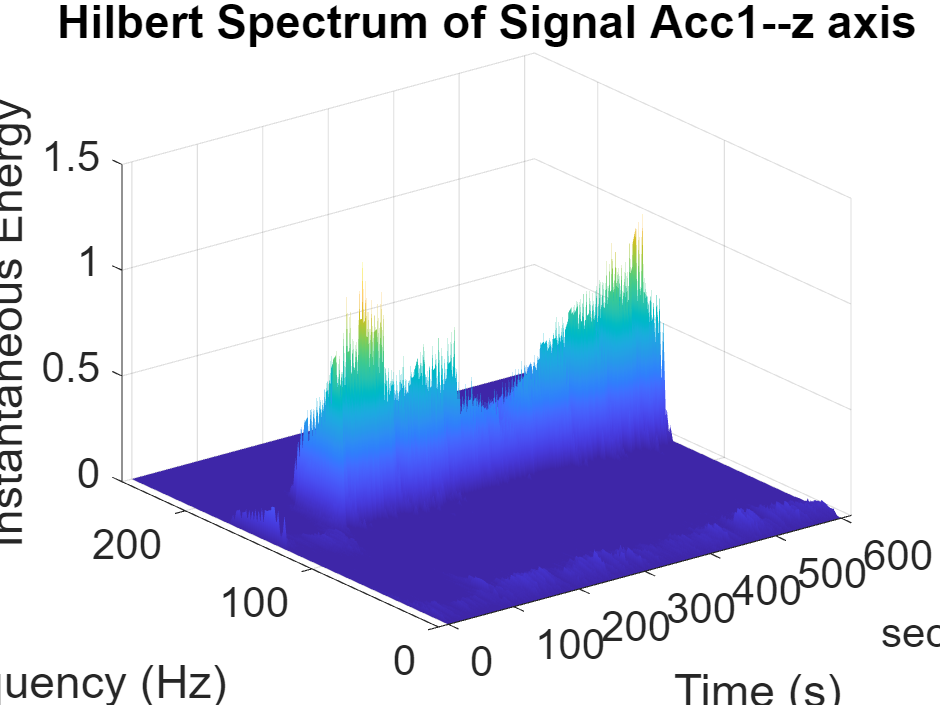

imf = emd(ZM_Acc1_z);
[hs,F,t] = hht(imf,Fs,'FrequencyLimits',[0 250]);

mesh(seconds(t),F,hs,'EdgeColor','none','FaceColor','interp')

title('Hilbert Spectrum of Signal Acc1--z axis','FontSize', 22)

ax = gca;
ax.FontSize = 18;
xlabel('Time (s)')
ylabel('Frequency (Hz)')
zlabel('Instantaneous Energy')

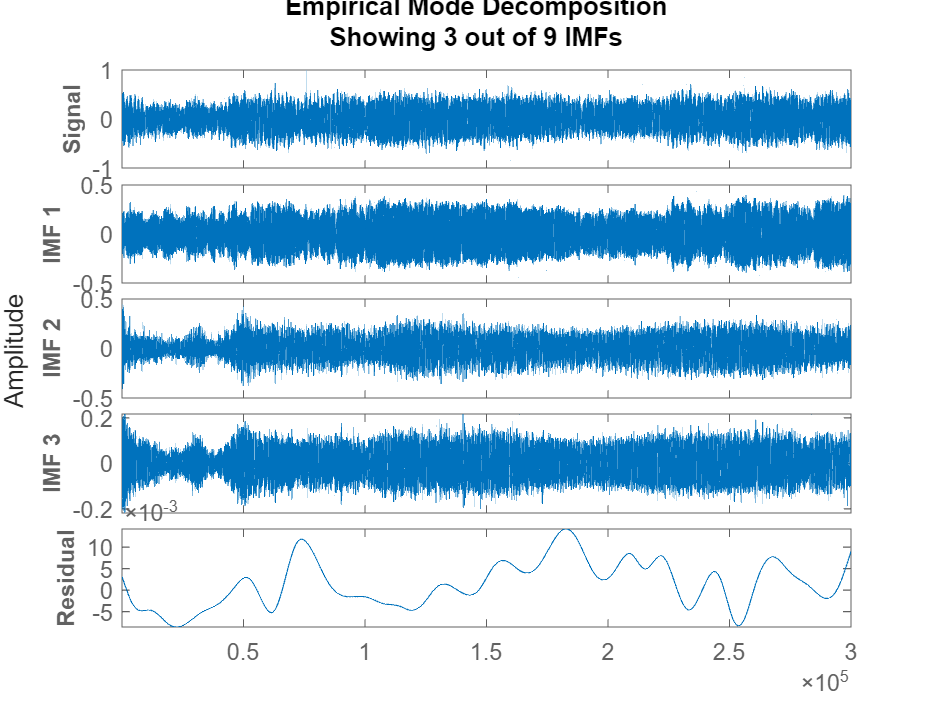

%Hilbert Spectral analysis accleration 1 signal - y axis

emd(ZM_Acc1_y,'MaxNumIMF',9)

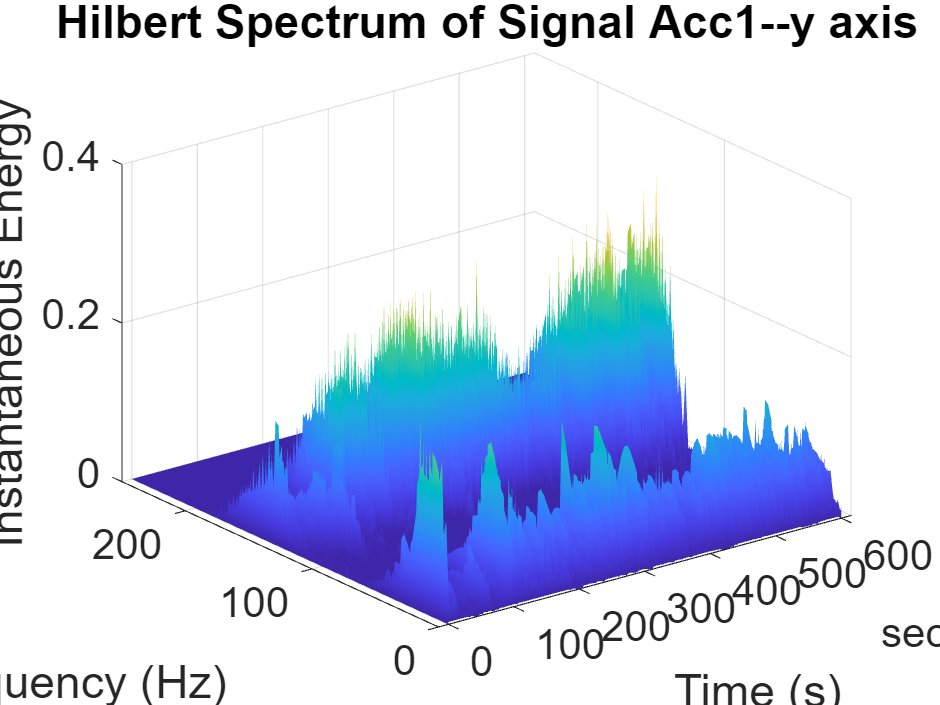

imf = emd(ZM_Acc1_y);
[hs,F,t] = hht(imf,Fs,'FrequencyLimits',[0 250]);

mesh(seconds(t),F,hs,'EdgeColor','none','FaceColor','interp')

title('Hilbert Spectrum of Signal Acc1--y axis','FontSize', 22)

ax = gca;
ax.FontSize = 18;
xlabel('Time (s)')
ylabel('Frequency (Hz)')
zlabel('Instantaneous Energy')

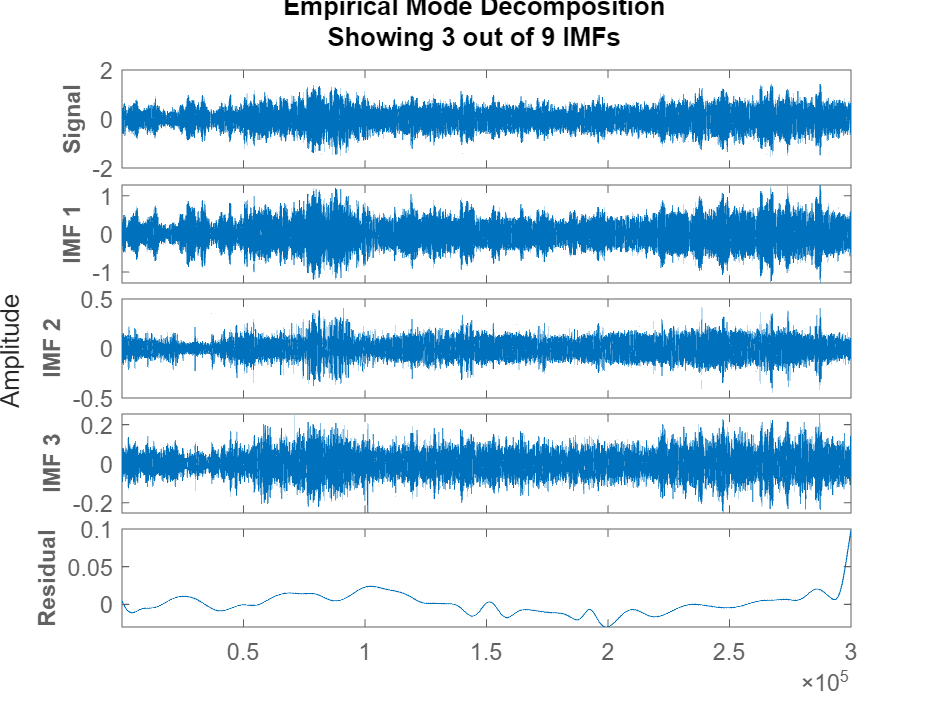

%Hilbert Spectral analysis accleration 1 signal - x axis

emd(ZM_Acc1_x,'MaxNumIMF',9)

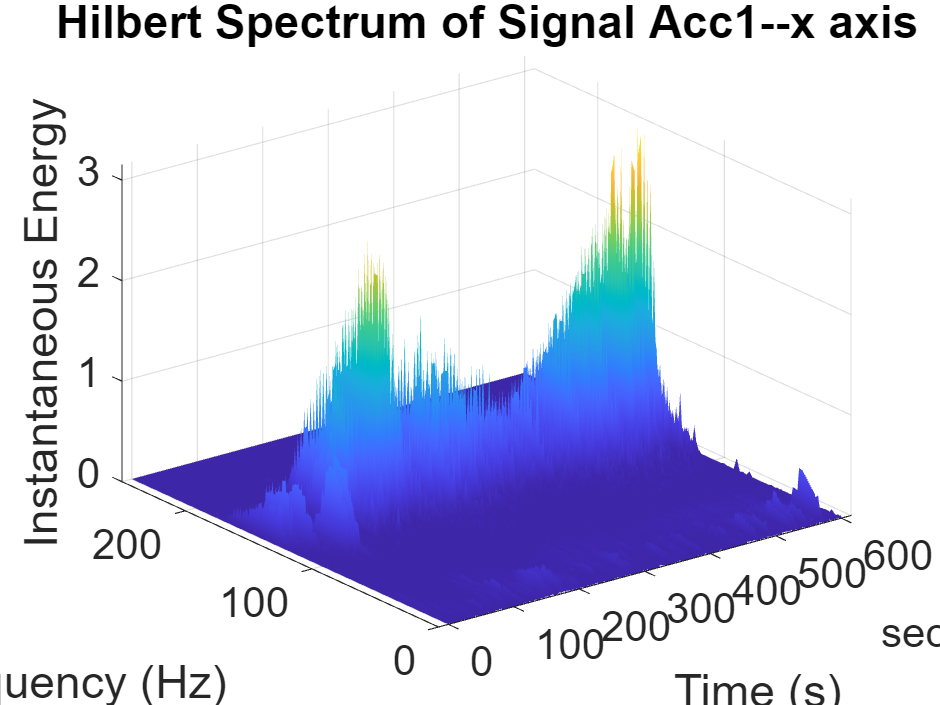

imf = emd(ZM_Acc1_x);
[hs,F,t] = hht(imf,Fs,'FrequencyLimits',[0 250]);

mesh(seconds(t),F,hs,'EdgeColor','none','FaceColor','interp')

title('Hilbert Spectrum of Signal Acc1--x axis','FontSize', 22)

ax = gca;
ax.FontSize = 18;
xlabel('Time (s)')
ylabel('Frequency (Hz)')
zlabel('Instantaneous Energy')